clc;close all;clear;clear drawArm;
load("system_parameters.mat");

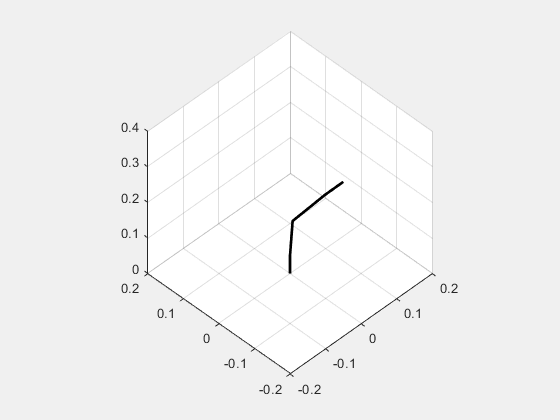

R = 0.032;
psi = pi/2;
point = [0.15;0;0.12]+R*[0;cos(psi);sin(psi)];
q = invKin([0 0 0],point,"ElbowUp",p);
T = fwdKin(q,p);

h = figure();
drawArm(T,h);


J = jac(T.T40(1:3,4),T)

J =    -0.0000   -0.1020   -0.0093   -0.0000
    0.1500    0.0000    0.0000    0.0000
         0    0.1500    0.1425    0.0500
         0    0.0000    0.0000    0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    0.0000    0.0000


J_inv = pinv(J)

J_inv =          0    0.1467         0         0         0    0.9780
  -10.8755    0.0000   -1.0931    0.0000   -0.0547   -0.0000
   11.7530   -0.0000   11.9881   -0.0000    0.5994    0.0000
   -0.8775   -0.0000  -10.8951    0.0000   -1.5448    0.0000



w4 = [0;0;-3e-3/T.T40(1,4)] % since the tip is on the x-axis, it is trivial to find w_z = v_y/o_4,x

w4 =          0
         0
   -0.0200


v4 = [0;-3e-3;0];

Xi = [v4;w4];

q_d = J_inv*Xi

q_d =    -0.0200
    0.0000
   -0.0000
   -0.0000
